# L. Natsakorn - 06 Feb 2024

## Show pair video for looking start time

videoTop = VideoReader('Top1.MOV');
videoSide = VideoReader('Side1.MOV');

% Create new video (Show pair videos)
frameWidth = videoTop.Width + videoSide.Width;
frameHeight = max(videoTop.Height, videoSide.Height);
outputVideoFile = 'combined_video.mp4';
outputVideo = VideoWriter(outputVideoFile, 'MPEG-4');
outputVideo.FrameRate = videoTop.FrameRate;

open(outputVideo);
% ::::::::::::: Setting Time ::::::::::::::
% Time in second unit when checker board appear in each video frame
videoTop.CurrentTime = min2sec(1, 38.5);
videoSide.CurrentTime = min2sec(0, 38);
% :::::::::::::::::::::::::::::::::::::::::
% Read frames from both videos and combine them
while hasFrame(videoTop) && hasFrame(videoSide)
    frame1 = readFrame(videoTop);
    frame2 = readFrame(videoSide);
    
    % Check if the current frame is within the specified time range
    if videoTop.CurrentTime <= min2sec(2, 1) && videoSide.CurrentTime <= min2sec(1, 0)
        % Resize frame2 to match the height of frame1 if needed
        if size(frame2, 1) < frameHeight
            frame2 = imresize(frame2, [frameHeight, NaN]);
        end
        
        % Combine frames side by side
        combinedFrame = [frame1, frame2];
        
        % Write the combined frame to the output video
        writeVideo(outputVideo, combinedFrame);
    end
    
    % Break the loop when the specified time ranges are reached
    if videoTop.CurrentTime >= 120 || videoSide.CurrentTime >= 60
        break;
    end
end

% Close the output video file
close(outputVideo);
disp(['Combined video', outputVideoFile]);


## Capture CheckerBoard

videoSide = VideoReader('Side1.MOV');
videoTop = VideoReader('Top1.MOV');
for sec = 38:1:60
    videoSide.CurrentTime = min2sec(0, sec);
    videoFrame = readFrame(videoSide);
    imwrite(videoFrame, "Calibrate-Side" + sec + ".png");
end
for sec = min2sec(1, 39):1:min2sec(1, 61)
    videoTop.CurrentTime = min2sec(0, sec);
    videoFrame = readFrame(videoTop);
    editframe = imresize(videoFrame, [1080, 1920]);
    imwrite(editframe, "Calibrate-Top" + sec + ".png");
end


## Detect Marker

videoTop = VideoReader('Top1.MOV');
videoSide = VideoReader('Side1.MOV');
startTimeTop =      min2sec(14, 16);
endTimeTop =        min2sec(14, 19);
startTimeSide =     min2sec(13, 15.4);
endTimeSide =       min2sec(13, 19);
videoTop.CurrentTime = startTimeTop;
videoSide.CurrentTime = startTimeSide;
videoTopFrame = imresize(readFrame(videoTop), [1080, 1920]);
videoSideFrame = imresize(readFrame(videoSide), [1080, 1920]);
videoTopFrameReal = undistortImage(videoTopFrame, stereoParams.CameraParameters1);
videoSideFrameReal = undistortImage(videoSideFrame, stereoParams.CameraParameters2);
% imshowpair(videoTopFrameReal, videoSideFrameReal, 'montage')
nFrame = 0;
miss = 0;
AXY_PinkTop = [0 0 0 0];
AXY_PinkSide = [0 0 0 0];
AXY_RedTop = [0 0 0 0];
AXY_RedSide = [0 0 0 0];
depVideoPlayer = vision.DeployableVideoPlayer;
myVideoTop = VideoWriter('TopViewDetected');
myVideoSide = VideoWriter('SideViewDetected');
myVideoCombine = VideoWriter('CombineDetected');
myVideoTop.FrameRate = 60;
myVideoSide.FrameRate = 60;
myVideoCombine.FrameRate = 60;

open(myVideoTop);
open(myVideoSide);
open(myVideoCombine);
while videoTop.CurrentTime <= endTimeTop && videoSide.CurrentTime <= endTimeSide
    nFrame = nFrame + 1;
    videoTopFrame = imresize(readFrame(videoTop), [1080, 1920]);
    videoSideFrame = imresize(readFrame(videoSide), [1080, 1920]);
    videoTopFrameReal = undistortImage(videoTopFrame, stereoParams.CameraParameters1);
    videoSideFrameReal = undistortImage(videoSideFrame, stereoParams.CameraParameters2);
    videoTopFrameRealedit = insertShape(videoTopFrameReal,"FilledPolygon",[1920 1 1688 1 1688 840 1 840 1 1080 1920 1080], 'Color', 'black', 'Opacity', 1);
    videoSideFrameRealedit = insertShape(videoSideFrameReal,"FilledPolygon",[1920 1 1000 1 1736 315 586 1080 1920 1080], 'Color', 'black', 'Opacity', 1);

    PinkmarkTop = imfill(createMaskPink(videoTopFrameRealedit, 1), 'holes');
    propertiesPinkTop   = table2array(struct2table(regionprops(PinkmarkTop, {'Area','centroid'})));
    PinkmarkSide = imfill(createMaskPink(videoSideFrameRealedit, 2), 'holes');
    propertiesPinkSide   = table2array(struct2table(regionprops(PinkmarkSide, {'Area','centroid'})));

    RedmarkTop = createMaskRed(videoTopFrameRealedit, 1);
    propertiesRedTop   = table2array(struct2table(regionprops(RedmarkTop, {'Area','centroid'})));
    RedmarkSide = createMaskRed(videoSideFrameRealedit, 2);
    propertiesRedSide   = table2array(struct2table(regionprops(RedmarkSide, {'Area','centroid'})));

    if((~isempty(propertiesPinkTop)) && (~isempty(propertiesPinkSide)) && (~isempty(propertiesRedTop)) && (~isempty(propertiesRedSide)))
        [AmaxPinkTop, ImaxPinkTop] = max(propertiesPinkTop(:, 1));
        AXY_PinkTop(nFrame, :) = [nFrame propertiesPinkTop(ImaxPinkTop, 1) propertiesPinkTop(ImaxPinkTop, 2) propertiesPinkTop(ImaxPinkTop, 3)];
        [AmaxPinkSide, ImaxPinkSide] = max(propertiesPinkSide(:, 1));
        AXY_PinkSide(nFrame, :) = [nFrame propertiesPinkSide(ImaxPinkSide, 1) propertiesPinkSide(ImaxPinkSide, 2) propertiesPinkSide(ImaxPinkSide, 3)];

        [AmaxRedTop, ImaxRedTop] = max(propertiesRedTop(:, 1));
        AXY_RedTop(nFrame, :) = [nFrame propertiesRedTop(ImaxRedTop, 1) propertiesRedTop(ImaxRedTop, 2) propertiesRedTop(ImaxRedTop, 3)];
        [AmaxRedSide, ImaxRedSide] = max(propertiesRedSide(:, 1));
        AXY_RedSide(nFrame, :) = [nFrame propertiesRedSide(ImaxRedSide, 1) propertiesRedSide(ImaxRedSide, 2) propertiesRedSide(ImaxRedSide, 3)];
    else
        AXY_PinkTop(nFrame, :) = AXY_PinkTop(nFrame - 1, :);
        AXY_PinkSide(nFrame, :) = AXY_PinkSide(nFrame - 1, :);
        AXY_RedTop(nFrame, :) = AXY_RedTop(nFrame - 1, :);
        AXY_RedSide(nFrame, :) = AXY_RedSide(nFrame - 1, :);
        miss = miss + 1;
    end
    videoTopFrameReal = insertShape(videoTopFrameReal,'rectangle',[AXY_PinkTop(nFrame, 3)-25 AXY_PinkTop(nFrame, 4)-25 50 50], 'LineWidth',5,'Color','magenta');
    videoTopFrameReal = insertShape(videoTopFrameReal,'rectangle',[AXY_RedTop(nFrame, 3)-25 AXY_RedTop(nFrame, 4)-25 50 50], 'LineWidth',5,'Color','blue');
%     depVideoPlayer(videoTopFrameReal);
    videoSideFrameReal = insertShape(videoSideFrameReal,'rectangle',[AXY_PinkSide(nFrame, 3)-25 AXY_PinkSide(nFrame, 4)-25 50 50], 'LineWidth',5,'Color','magenta');
    videoSideFrameReal = insertShape(videoSideFrameReal,'rectangle',[AXY_RedSide(nFrame, 3)-25 AXY_RedSide(nFrame, 4)-25 50 50], 'LineWidth',5,'Color','blue');
%     depVideoPlayer(videoSideFrameReal);
    for i = 1:nFrame
        videoTopFrameReal = insertShape(videoTopFrameReal,'circle',[AXY_PinkTop(i, 3:4),3],...
            'LineWidth',5,'Color','magenta');
        videoTopFrameReal = insertShape(videoTopFrameReal,'circle',[AXY_RedTop(i, 3:4),3],...
            'LineWidth',5,'Color','blue');
        videoSideFrameReal = insertShape(videoSideFrameReal,'circle',[AXY_PinkSide(i, 3:4),3],...
            'LineWidth',5,'Color','magenta');
        videoSideFrameReal = insertShape(videoSideFrameReal,'circle',[AXY_RedSide(i, 3:4),3],...
            'LineWidth',5,'Color','blue');
    end
    combinedFrame = [videoTopFrameReal, videoSideFrameReal];
    depVideoPlayer(combinedFrame);
    writeVideo(myVideoTop, videoTopFrameReal);
    writeVideo(myVideoSide, videoSideFrameReal);
    writeVideo(myVideoCombine, combinedFrame);
end
worldPoints = triangulate([AXY_PinkTop(:, 3) AXY_PinkTop(:, 4)], [AXY_PinkSide(:, 3) AXY_PinkSide(:, 4)], stereoParams);
worldPointsRed = triangulate([AXY_RedTop(:, 3) AXY_RedTop(:, 4)], [AXY_RedSide(:, 3) AXY_RedSide(:, 4)], stereoParams);

close(myVideoTop);
close(myVideoSide);
close(myVideoCombine);

## Plot 3D Paths

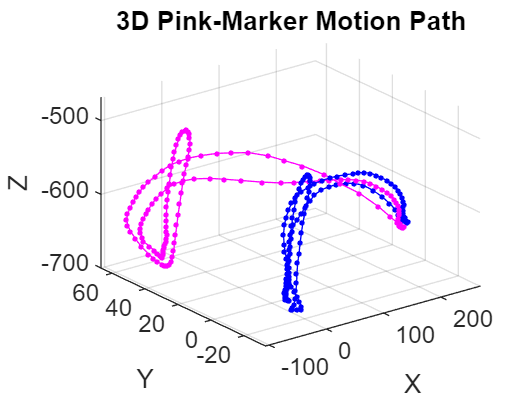

figure;
plot3(worldPoints(:,1), -1 .* worldPoints(:,2), -1 .* worldPoints(:,3), 'm.-');
hold on
plot3(worldPointsRed(:,1), -1 .* worldPointsRed(:,2), -1 .* worldPointsRed(:,3), 'b.-');
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Pink-Marker Motion Path');
hold off

## Plot Aperture

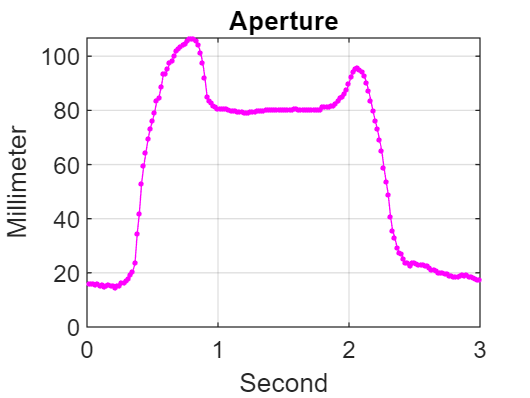

figure;
plot((1:length(worldPointsRed(:,2)))/60, sqrt((worldPoints(:,1) - worldPointsRed(:,1)).^2 + (worldPoints(:,2) - worldPointsRed(:,2)).^2), 'm.-');
grid on;
xlabel('Second');
ylabel('Millimeter');
title('Aperture');

function minute = min2sec(min, sec)
    minute = min * 60 + sec;
    return
end

function [BW,maskedRGBImage] = createMaskPink(RGB, view)
I = rgb2hsv(RGB);
% view : 1 = Top, 2 = Side
channel1Min = [0.816 0.805];
channel1Max = [0.927 0.988];
channel2Min = [0.113 0.188];
channel2Max = [1.000 1.000];
channel3Min = [0.632 0.516];
channel3Max = [1.000 1.000];
sliderBW = (I(:,:,1) >= channel1Min(view) ) & (I(:,:,1) <= channel1Max(view)) & ...
    (I(:,:,2) >= channel2Min(view) ) & (I(:,:,2) <= channel2Max(view)) & ...
    (I(:,:,3) >= channel3Min(view) ) & (I(:,:,3) <= channel3Max(view));
BW = sliderBW;
maskedRGBImage = RGB;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
end

function [BW,maskedRGBImage] = createMaskRed(RGB, view)
I = rgb2hsv(RGB);
% view : 1 = Top, 2 = Side
channel1Min = [0.982 0.993];
channel1Max = [0.034 0.060];
channel2Min = [0.481 0.476];
channel2Max = [1.000 1.000];
channel3Min = [0.524 0.460];
channel3Max = [0.839 0.763];
sliderBW = (I(:,:,1) >= channel1Min(view) ) | (I(:,:,1) <= channel1Max(view)) & ...
    (I(:,:,2) >= channel2Min(view) ) & (I(:,:,2) <= channel2Max(view)) & ...
    (I(:,:,3) >= channel3Min(view) ) & (I(:,:,3) <= channel3Max(view));
BW = sliderBW;
maskedRGBImage = RGB;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
end